This is a livescript to create boxplots for the manuscript.

%Boxplot for anticipatory summary image:
intermedpath='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles'; 
load(fullfile(intermedpath,'data_frame'),'df');
%load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\vectorized_images_full_masked_10_percent.mat')
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_sum_g_rnd_neg_ptfce.nii.gz'

img = 'C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_sum_g_rnd_neg_ptfce.nii.gz'

thresholdfrommaxstat=4.21%this is the one sided, while 4.62 is the twosided previous run.this is a bit different, not sure why exactly...

thresholdfrommaxstat = 4.2100

vectorizedimg=v_masked_BK(img);

Compressed NIfTI files are not supported.


vectorizedimg_masked=vectorizedimg(dfv_masked.anticip_brainmask);
signifmask=vectorizedimg_masked>thresholdfrommaxstat;
sum(signifmask)

ans = 99

activity=[];
counter=1;
for studyrank=1:height(df)
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1})
        activity.antplac(counter)=avgnormalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask));
%         normalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask))
        activity.antcontr(counter)=avgnormalize(dfv_masked.anticip_control{studyrank,1}(:,signifmask));
%         activity.painplac(counter)=avgnormalize(dfv_masked.pain_placebo{studyrank,1}(:,signifmask));
%         activity.paincontr(counter)=avgnormalize(dfv_masked.pain_control{studyrank,1}(:,signifmask));
        activity.studynm(counter)=df.study_ID(studyrank);
        counter=counter+1;
    end


end
% Convert struct fields into cell arrays
name_cell = activity.studynm';
ap_cell= num2cell(activity.antplac');
ac_cell=num2cell(activity.antcontr');


% Combine cell arrays into a single cell array
combined_cell = [name_cell, ap_cell, ac_cell];

% Specify the file name
file_name = 'C:\Users\lenov\Documents\PICO\C_calculations\D_results\boxplots\anticip_sum_negFWERcluster.csv';
% Convert cell array to a table
T = cell2table(combined_cell, 'VariableNames', {'studyid', 'anticip_placebo',   'anticip_control'});

% Write table to a CSV file
writetable(T, file_name);

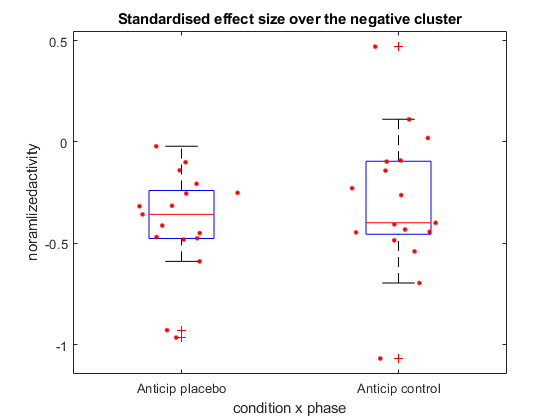

data = [activity.antplac' activity.antcontr'];
figure()
% Create a boxplot
boxplot(data, 'Labels', {'Anticip placebo', 'Anticip control'});
title('Standardised effect size over the negative cluster');
xlabel('condition x phase');
ylabel('noramlizedactivity');
hold on;  % Allow multiple plots on the same axes

% Plot individual data points as an overlay
numGroups = size(data, 2);
for i = 1:numGroups
    x = i + randn(size(data, 1), 1) * 0.1;  % Add jitter for visibility
    plot(x, data(:, i), 'r.', 'MarkerSize', 10);
end
numGroups = size(data, 1);
colors = colormap(lines(numGroups));

%Boxplot for anticipatory difference image:
intermedpath='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles'; 
load(fullfile(intermedpath,'data_frame'),'df');
%load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\vectorized_images_full_masked_10_percent.mat')
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_g_rnd_neg_ptfce.nii.gz'

img = 'C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_g_rnd_neg_ptfce.nii.gz'

thresholdfrommaxstat=4.5%this is the one sided, while 4.62 is the twosided previous run.this is a bit different, not sure why exactly...

thresholdfrommaxstat = 4.5000

vectorizedimg=v_masked_BK(img);

Compressed NIfTI files are not supported.


vectorizedimg_masked=vectorizedimg(dfv_masked.anticip_brainmask);
signifmask=vectorizedimg_masked>thresholdfrommaxstat;
sum(signifmask)

ans = 300

%This is for the correlation:
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);


activity=[];
counter=1;
for studyrank=1:height(df)
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1})
        activity.antplac(counter)=avgnormalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask));
%         normalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask))
        activity.antcontr(counter)=avgnormalize(dfv_masked.anticip_control{studyrank,1}(:,signifmask));
%         activity.painplac(counter)=avgnormalize(dfv_masked.pain_placebo{studyrank,1}(:,signifmask));
%         activity.paincontr(counter)=avgnormalize(dfv_masked.pain_control{studyrank,1}(:,signifmask));
        activity.studynm(counter)=df.study_ID(studyrank);
        counter=counter+1;
    end


end
% Convert struct fields into cell arrays
name_cell = activity.studynm';
ap_cell= num2cell(activity.antplac');
ac_cell=num2cell(activity.antcontr');


% Combine cell arrays into a single cell array
combined_cell = [name_cell, ap_cell, ac_cell];

% Specify the file name
file_name = 'C:\Users\lenov\Documents\PICO\C_calculations\D_results\boxplots\anticip_diff_negFWERcluster.csv';
% Convert cell array to a table
T = cell2table(combined_cell, 'VariableNames', {'studyid', 'anticip_placebo',   'anticip_control'});

% Write table to a CSV file
writetable(T, file_name);

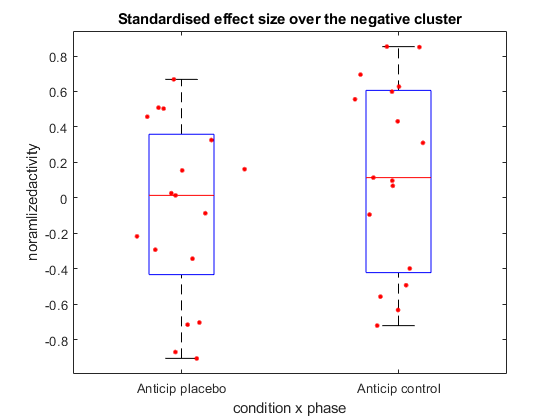


data = [activity.antplac' activity.antcontr'];
figure()
% Create a boxplot
boxplot(data, 'Labels', {'Anticip placebo', 'Anticip control'});
title('Standardised effect size over the negative cluster');
xlabel('condition x phase');
ylabel('noramlizedactivity');
hold on;  % Allow multiple plots on the same axes

% Plot individual data points as an overlay
numGroups = size(data, 2);
for i = 1:numGroups
    x = i + randn(size(data, 1), 1) * 0.1;  % Add jitter for visibility
    plot(x, data(:, i), 'r.', 'MarkerSize', 10);
end
numGroups = size(data, 1);
colors = colormap(lines(numGroups));

% This is a scatter plot of the ß estimates and the behavioral analgesia
i=1;

img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii.gz';
vectorized_img=v_masked_BK(img);

Compressed NIfTI files are not supported.


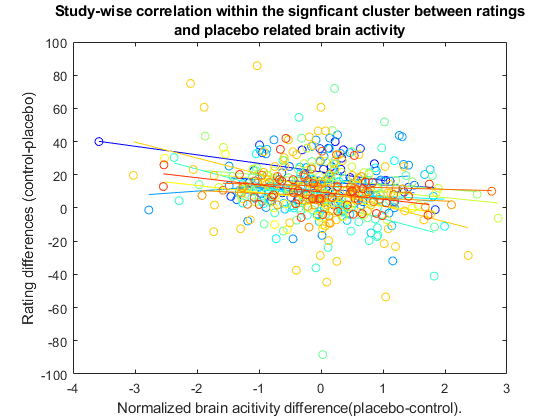

thrshold.corr=4.42;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);

allratingsnorm=[];
allbrainactivitynorm=[];
all=[];
allbrainactivity=[];
%  figure()
h = figure;
inludedstudies=[];
i=1;
for studyrank=1:height(df) %stats
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && ~isempty(df.GIV_stats_rating101(studyrank).delta)
        ratings=normalize(df.GIV_stats_rating101(studyrank).delta);
        all.ratings{i}=df.GIV_stats_rating101(studyrank).delta;
        all.brainactivityplac{i}=mean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked),2,'omitnan');
        all.brainactivitycont{i}=mean(dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked),2,'omitnan');
        all.brainactivityplac_norm{i}=normalize(all.brainactivityplac{i});
        all.brainactivitycont_norm{i}=normalize(all.brainactivitycont{i});
        all.studynm{i}=repmat(df.study_ID(studyrank),length(all.ratings{i}),1);
        ratings=-df.GIV_stats_rating101(studyrank).delta;
        normbrainact=normalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked)- ...
            dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked));
        avgnormbrainact=mean(normbrainact,2,'omitnan');
        cmap=jet(17);
        
        scatter(avgnormbrainact,ratings,[],cmap(i,:));
        Fit = polyfit(avgnormbrainact,ratings,1); % x = x data, y = y data, 1 = order of the polynomial i.e a straight line 
        plot(avgnormbrainact,polyval(Fit,avgnormbrainact),'Color',cmap(i,:))
        hold on
        i=i+1;

        inludedstudies=[inludedstudies, studyrank];


    end
  
    
end
title({'Study-wise correlation within the signficant cluster between ratings' 'and placebo related brain activity'})
xlabel('Normalized brain acitivity difference(placebo-control).') 
ylabel('Rating differences (control-placebo)')
hold off
print(h,'correlationinputamen','-dpdf','-r0')

%lgd=legend(df.study_ID(inludedstudies),'Location','eastoutside');



combined_cell = [vertcat(all.studynm{:}), num2cell(vertcat(all.ratings{:})), ...
    num2cell(vertcat(all.brainactivityplac{:})),...
    num2cell(vertcat(all.brainactivitycont{:})),...
    num2cell(vertcat(all.brainactivityplac_norm{:})),...
    num2cell(vertcat(all.brainactivitycont_norm{:}))];

% Specify the file name
file_name = 'C:\Users\lenov\Documents\PICO\C_calculations\D_results\boxplots\anticip_diff_corr_negFWERcluster.csv';
% Convert cell array to a table
T = cell2table(combined_cell,'VariableNames', {'studyid', 'ratings','anticip_placebo',   'anticip_control','anticip_placebo_norm',   'anticip_control_norm'});

% Write table to a CSV file
writetable(T, file_name);

% chleg = get(lgd,'children');
% for maki=1:length(inludedstudies)
%     set(chleg(maki),'color',cmap(maki,:))
% end
%lgd.FontSize=6;
%lgd.NumColumns = 2;


function meannoramlizeddata=avgnormalize(data)
    %this function (assuming each column represent a different voxel),
    %normalize the indiviudal voxel level values andd calculates the mean
    %of it.
    meannoramlizeddata=mean(mean(data,'omitnan')./std(data,'omitnan'),'omitnan');
end

function normalizeddata=normalize(data)
    %this function (assuming each column represent a different voxel),
    %normalize the indiviudal voxel level values
    normalizeddata=(data-mean(data,'omitnan'))./std(data,'omitnan');
end
